## Submission for HW3 - get_satpos.m

clear;
pwd;
% add products, hw03 folder to path
currPath = strcat(pwd,'/SIOG_GNSS-GPS/SIOG230_GNS_Geodesy/matlab_utils/');
addpath('/Users/p3choi/SIOG_GNSS-GPS/SIOG230_GNS_Geodesy/products/');
addpath('/Users/p3choi/SIOG_GNSS-GPS/SIOG230_GNS_Geodesy/hw03/');


Function gets the correct X, Y, Z for the broadcast input

[ephBrdc,~,~,~] = ...
    read_rinexn(['/Users/p3choi/SIOG_GNSS-GPS/' ...
    'SIOG230_GNS_Geodesy/products/epgga9.292']);

-------------
Reading /Users/p3choi/SIOG_GNSS-GPS/SIOG230_GNS_Geodesy/products/epgga9.292



% 1st epoch
tin = 6*24*3600;
sv = 31;
[X, Y, Z] = get_satpos(tin, sv, ephBrdc);
disp([num2str(X),' ', num2str(Y), ' ', num2str(Z)]);

2775136.6936 -16575847.4654 20443682.8846



% last epoch
tin2 = 6*24*3600 +24*3600 - 15*60;
[X, Y, Z] = get_satpos(tin2, sv, ephBrdc);
disp([num2str(X),' ', num2str(Y), ' ', num2str(Z)]);

1469367.4917 -17645753.4532 19639438.6774


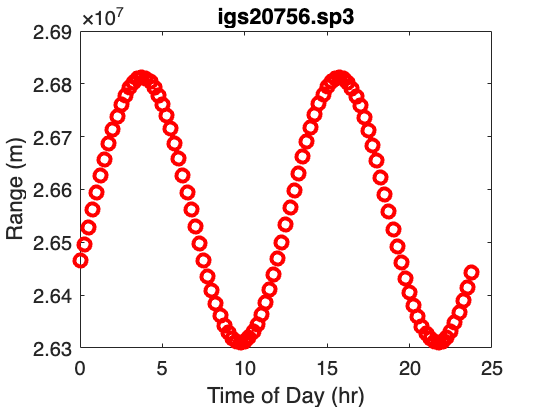


%%%% Read igs20756.sp3
%#cP2019 10 19
[sp3,sv_all,excl_sat] = read_sp3(['/Users/p3choi/SIOG_GNSS-GPS/'...
    'SIOG230_GNS_Geodesy/products/igs20756.sp3']);

Ts = sp3.prn31(:,1).';
Xs = sp3.prn31(:,2).';
Ys = sp3.prn31(:,3).';
Zs = sp3.prn31(:,4).';
dTs = sp3.prn31(:,5).';

Ts_hr = Ts/(3600);
clf;
hold off;
ranges = sqrt(Xs.^2 + Ys.^2 + Zs.^2);
plot(Ts_hr,ranges,"ro",LineWidth=2);
title("igs20756.sp3");
xlabel("Time of Day (hr)");
ylabel("Range (m)");

%%%%%%%%%%
%%% Compute differences btw epgga9.292 (Day 292 of 2019) and igs20756.sp3
[ephBrdc,~,~,~] = ...
    read_rinexn(['/Users/p3choi/SIOG_GNSS-GPS/' ...
    'SIOG230_GNS_Geodesy/products/epgga9.292']);

-------------
Reading /Users/p3choi/SIOG_GNSS-GPS/SIOG230_GNS_Geodesy/products/epgga9.292


% Choose satellite PRN = 31
sv = 31;

% Choose correct starting epoch: day 6
t0 = 6*24*3600;
tf = 6*24*3600+24*3600-15*60;

% Advance every 15 minutes
dt = 15*60;
N = length(Ts);
ts = zeros(size(Ts));
for i=0:N-1
     ts(i+1) = t0 + i*dt;
end

% Create pos arrays same length as t
Xarr3 = zeros(size(Ts));
Yarr3 = zeros(size(Ts));
Zarr3 = zeros(size(Ts));


for i=1:N
    [X3, Y3, Z3] = get_satpos(ts(i), sv, ephBrdc);
    Xarr3(i) = X3;
    Yarr3(i) = Y3;
    Zarr3(i) = Z3;
end

my_sat_pos = [Ts.', Xarr3.', Yarr3.', Zarr3.'];


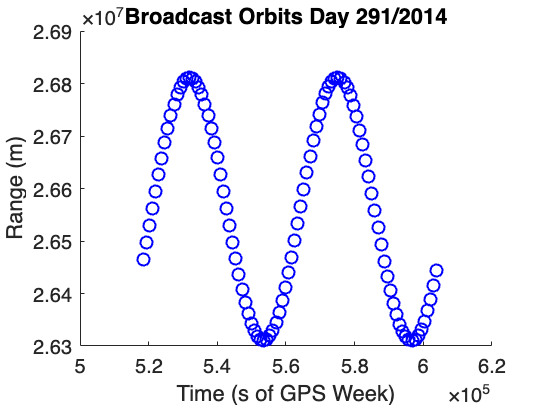



clf;
hold on;
range3 = sqrt(Xarr3.^2 + Yarr3.^2 + Zarr3.^2);
plot(ts,range3,"bo",LineWidth=1);
title("Broadcast Orbits Day 291/2014");
xlabel("Time (s of GPS Week)");
ylabel("Range (m)");
hold off;

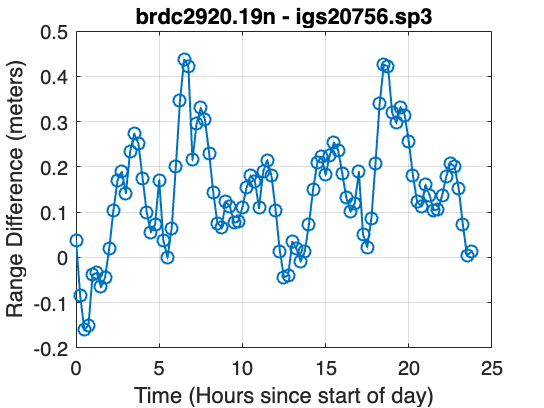

% Range Difference
clf;
rangediff = range3-ranges;
plot(Ts_hr, rangediff,"-o",LineWidth=1);
title("brdc2920.19n - igs20756.sp3");
xlabel('Time (Hours since start of day)');
ylabel('Range Difference (meters)');
grid on;

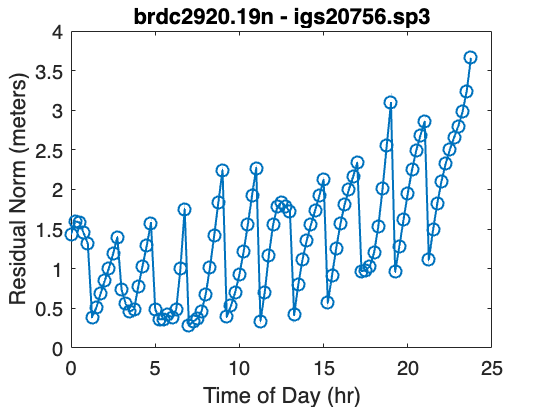


% Length of Difference Vector
diffvec = sqrt((Xarr3-Xs).^2 + (Yarr3-Ys).^2 + (Zarr3-Zs).^2);
clf;
plot(Ts_hr, diffvec,"-o",LineWidth=1);
title("brdc2920.19n - igs20756.sp3");
xlabel("Time of Day (hr)");
ylabel("Residual Norm (meters)");

Compute **Range Difference**


$$\sqrt(X_e^2 + Y_e^2 + Z_e^2) - \sqrt(X_p^2 + Y_p^2 + Z_p^2)$$


The **Length of the Difference Vector (Residual Norm)** 


$$\sqrt(X_e -X_p)^2 + (Y_e-Y_p)^2 +(Z_p- Z_e^2)$$


becomes greater after every time of ephemeris (2 hours or so). Error between broadcast orbits and precise orbits increases until the next `toe`. 